clc %clears the command window
close all %close all windows
clear all %clears the workspace

Path = '/Users/mac/Desktop/FYP/Code and Data/Data Collection/';
warning("off")

colaccX = 3;
colaccY = 4;
colaccZ = 5;

colgyroX = 10;
colgyroY = 11;
colgyroZ = 12;

colgravX = 21;
colgravY = 22;
colgravZ = 23;

M = 32;

Path_Disha= '/Users/mac/Desktop/FYP/Code and Data/Data Files/';
warning("off")

colaccX_Disha = 1;
colaccY_Disha = 2;
colaccZ_Disha = 3;

colgyroX_Disha = 4;
colgyroY_Disha = 5;
colgyroZ_Disha = 6;

M_Disha = 64;

% Filename46 = string(Path) + 'Player 17/M.Me.S.17.1.csv';
% Filename47 = string(Path) + 'Player 17/M.Me.S.17.2.csv';
% Filename51 = string(Path) + 'Player 16/M.E.S.16.csv';
% Filename56 = string(Path) + 'Player 15/M.E.S.15.csv';
% Filename57 = string(Path) + 'Player 24/F.E.S.24.csv';
% Filename58 = string(Path) + 'Player 25/F.E.S.25.csv';


% Filename46 = string(Path) + 'Player 17/M.Me.Fd.17.1.csv';
% Filename47 = string(Path) + 'Player 17/M.Me.Fd.17.2.csv';
% Filename51 = string(Path) + 'Player 17/M.Me.Fd.17.3.csv';
% Filename56 = string(Path) + 'Player 16/M.E.Fd.16.csv';
% Filename57 = string(Path) + 'Player 23/M.Me.Fd.23.1.csv';
% Filename58 = string(Path) + 'Player 23/M.Me.Fd.23.2.csv';

% Filename46 = string(Path) + 'Player 17/M.Me.Bd.17.1.csv';
% Filename47 = string(Path) + 'Player 17/M.Me.Bd.17.2.csv';
% Filename51 = string(Path) + 'Player 17/M.Me.Bd.17.3.csv';
% Filename56 = string(Path) + 'Player 16/M.E.Bd.16.csv';
% Filename57 = string(Path) + 'Player 23/M.Me.Bd.23.1.csv';
% Filename58 = string(Path) + 'Player 23/M.Me.Bd.23.2.csv';

% Filename46 = string(Path) + 'Player 23/M.Me.FdV.23.1.csv';
% Filename47 = string(Path) + 'Player 23/M.Me.FdV.23.2.csv';
% Filename51 = string(Path) + 'Player 23/M.Me.FdV.23.3.csv';
% Filename56 = string(Path) + 'Player 24/F.E.FdV.24.csv';
% Filename57 = string(Path) + 'Player 25/F.E.FdV.25.csv';
% Filename58 = string(Path) + 'Player 23/M.Me.FdV.23.2.csv';

Filename46 = string(Path) + 'Player 23/M.Me.BdV.23.1.csv';
Filename47 = string(Path) + 'Player 23/M.Me.BdV.23.2.csv';
Filename51 = string(Path) + 'Player 24/F.E.BdV.24.csv';
Filename56 = string(Path) + 'Player 25/F.E.BdV.25.csv';
Filename57 = string(Path) + 'Player 24/F.E.BdV.24.csv';
Filename58 = string(Path) + 'Player 25/F.E.BdV.25.csv';

files_fdE = [Filename46,Filename47, Filename51, Filename56, Filename57, Filename58];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_volley_trial(files_fdE, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);
[faMax,faMin,faMean,faStd,faArea,fgMax,fgMin,fgMean,fgStd,fgArea,fgravMax,fgravMin,fgravMean,fgravStd,fgravArea] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 22.0163

% Filename48 = string(Path) + 'Player 21/F.B.S.21.1.csv';
% Filename49 = string(Path) + 'Player 21/F.B.S.21.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.S.21.3.csv';
% Filename52 = string(Path) + 'Player 22/M.B.S.22.1.csv';
% Filename53 = string(Path) + 'Player 22/M.B.S.22.2.csv';
% Filename54 = string(Path) + 'Player 26/F.B.S.26.1.csv';
% Filename55 = string(Path) + 'Player 26/F.B.S.26.2.csv';
% 
% Filename48 = string(Path) + 'Player 20/F.B.Fd.20.1.csv';
% Filename49 = string(Path) + 'Player 20/F.B.Fd.20.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.Fd.21.1.csv';
% Filename52 = string(Path) + 'Player 22/M.B.Fd.22.1.csv';
% Filename53 = string(Path) + 'Player 26/F.B.Fd.26.1.csv';
% Filename54 = string(Path) + 'Player 26/F.B.Fd.26.2.csv';
% Filename55 = string(Path) + 'Player 27/F.B.Fd.27.1.csv';

% Filename48 = string(Path) + 'Player 20/F.B.Bd.20.1.csv';
% Filename49 = string(Path) + 'Player 20/F.B.Bd.20.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.Bd.21.1.csv';
% Filename52 = string(Path) + 'Player 21/F.B.Bd.21.2.csv';
% Filename53 = string(Path) + 'Player 22/M.B.Bd.22.1.csv';
% Filename54 = string(Path) + 'Player 26/F.B.Bd.26.1.csv';
% Filename55 = string(Path) + 'Player 27/F.B.Bd.27.1.csv';

% Filename48 = string(Path) + 'Player 21/F.B.FdV.21.1.csv';
% Filename49 = string(Path) + 'Player 21/F.B.FdV.21.2.csv';
% Filename50 = string(Path) + 'Player 21/F.B.FdV.21.2.csv';
% Filename52 = string(Path) + 'Player 26/F.B.FdV.26.1.csv';
% Filename53 = string(Path) + 'Player 26/F.B.FdV.26.2.csv';
% Filename54 = string(Path) + 'Player 27/F.B.FdV.27.1.csv';
% Filename55 = string(Path) + 'Player 27/F.B.FdV.27.2.csv';

Filename48 = string(Path) + 'Player 21/F.B.BdV.21.1.csv';
Filename49 = string(Path) + 'Player 21/F.B.BdV.21.2.csv';
Filename50 = string(Path) + 'Player 26/F.B.BdV.26.1.csv';
Filename52 = string(Path) + 'Player 26/F.B.BdV.26.2.csv';
Filename53 = string(Path) + 'Player 27/F.B.BdV.27.1.csv';
Filename54 = string(Path) + 'Player 27/F.B.BdV.27.2.csv';
Filename55 = string(Path) + 'Player 21/F.B.BdV.21.2.csv';


files_fdB = [Filename48,Filename49,Filename50,Filename52,Filename53,Filename54,Filename55];

[AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ] = Compile_volley_trial(files_fdB, M, colaccX,colaccY,colaccZ,colgyroX,colgyroY,colgyroZ,colgravX,colgravY,colgravZ);
[faMaxB,faMinB,faMeanB,faStdB,faAreaB,fgMaxB,fgMinB,fgMeanB,fgStdB,fgAreaB,fgravMaxB,fgravMinB,fgravMeanB,fgravStdB,fgravAreaB] = MaxMin_trial(AllfGyroX,AllfGyroY,AllfGyroZ,AllfAccelX,AllfAccelY,AllfAccelZ,AllfGravX,AllfGravY,AllfGravZ);
[RacketSpeedAverage] = RacketSpeed(AllfGyroY, AllfGyroZ);

RacketSpeedAverage = 20.3220

start_train = 1;
finish_train_B = 26;
finish_train_E = 26;


aMaxAll=vertcat(faMax(start_train:finish_train_E,:),faMaxB(start_train:finish_train_B,:));
aMinAll=vertcat(faMin(start_train:finish_train_E,:),faMinB(start_train:finish_train_B,:));
aMeanAll=vertcat(faMean(start_train:finish_train_E,:),faMeanB(start_train:finish_train_B,:));
aStdAll=vertcat(faStd(start_train:finish_train_E,:),faStdB(start_train:finish_train_B,:));
aAreaAll=vertcat(faArea(start_train:finish_train_E,:),faAreaB(start_train:finish_train_B,:));
gMinAll=vertcat(fgMin(start_train:finish_train_E,:),fgMinB(start_train:finish_train_B,:));
gMaxAll=vertcat(fgMax(start_train:finish_train_E,:),fgMaxB(start_train:finish_train_B,:));
gMeanAll=vertcat(fgMean(start_train:finish_train_E,:),fgMeanB(start_train:finish_train_B,:));
gStdAll=vertcat(fgStd(start_train:finish_train_E,:),fgStdB(start_train:finish_train_B,:));
gAreaAll=vertcat(fgArea(start_train:finish_train_E,:),fgAreaB(start_train:finish_train_B,:));
gravMinAll=vertcat(fgravMin(start_train:finish_train_E,:),fgravMinB(start_train:finish_train_B,:));
gravMaxAll=vertcat(fgravMax(start_train:finish_train_E,:),fgravMaxB(start_train:finish_train_B,:));
gravMeanAll=vertcat(fgravMean(start_train:finish_train_E,:),fgravMeanB(start_train:finish_train_B,:));
gravStdAll=vertcat(fgravStd(start_train:finish_train_E,:),fgravStdB(start_train:finish_train_B,:));
gravAreaAll=vertcat(fgravArea(start_train:finish_train_E,:),fgravAreaB(start_train:finish_train_B,:));

Class(1:finish_train_E,1)=1; %Expert 5
Class(finish_train_E+1:finish_train_E+finish_train_B,1)=2; %Beginners 5

fullArray=horzcat(aMaxAll,aMinAll,aMeanAll,aStdAll,aAreaAll,gMaxAll,gMinAll,gMeanAll,gStdAll,gAreaAll,gravMaxAll,gravMinAll,gravMeanAll,gravStdAll,gravAreaAll,Class);

%normalize/standardize all elements in the array
means=mean(fullArray);
stds=std(fullArray);
normfullArray = zeros(size(fullArray,1),size(fullArray,2)-1);
for i=1:size(fullArray,2)-1
    normfullArray(:,i)=(fullArray(:,i)-means(1,i))/stds(1,i);
end

normfullArray2=horzcat(normfullArray,Class);
colNames={'aXmax','aYmax','aZmax','aXmin','aYmin','aZmin','aXmean','aYmean','aZmean','aXstd','aYstd','aZstd','aXArea','aYArea','aZArea','gXmax','gYmax','gZmax','gXmin','gYmin','gZmin','gXmean','gYmean','gZmean','gXstd','gYstd','gZstd','gXArea','gYArea','gZArea','gravXmax','gravYmax','gravZmax','gravXmin','gravYmin','gravZmin','gravXmean','gravYmean','gravZmean','gravXstd','gravYstd','gravZstd','gravXArea','gravYArea','gravZArea','Class'};
completeTable=array2table(fullArray,'VariableNames',colNames)

completeTable = 52×46 table
     aXmax       aYmax      aZmax       aXmin       aYmin       aZmin      aXmean     aYmean      aZmean      aXstd      aYstd      aZstd     aXArea     aYArea    aZArea      gXmax      gYmax     gZmax      gXmin       gYmin      gZmin       gXmean       gYmean        gZmean       gXstd      gYstd      gZstd     gXArea     gYArea      gZArea     gravXmax     gravYmax    gravZmax    gravXmin 

writetable(completeTable, 'level_class_Bd.csv')

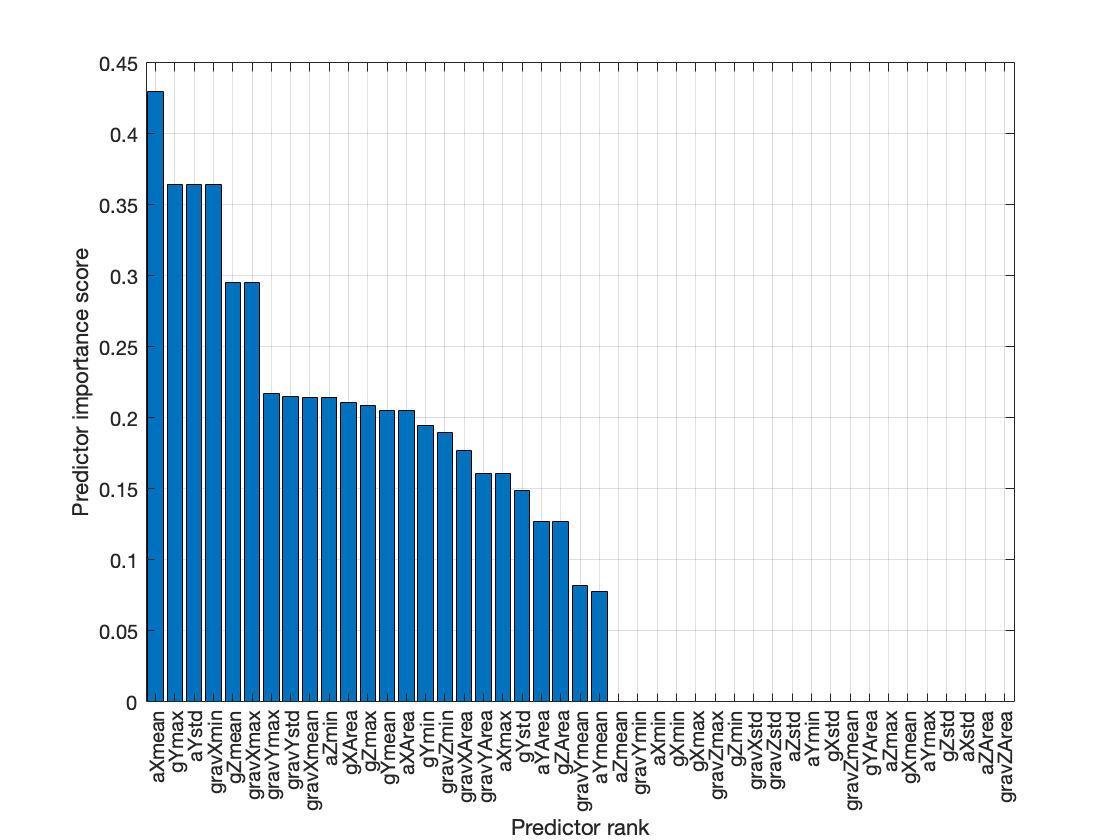

X = completeTable(:,1:45);
Y = completeTable(:,46);

[idx,scores] = fscmrmr(X,Y);
varnames = completeTable.Properties.VariableNames(idx);
work1=cellstr(varnames);
work2 = strrep(work1, '_', '\_');
labels = nominal(work2);
labels = reordercats(labels, string(labels));

figure
bar(labels,scores(idx))
grid on
xlabel('Predictor rank')
ylabel('Predictor importance score')
% xticklabels(strrep(completeTable.Properties.VariableNames(idx),'_','\_'))
xtickangle(90)


% t_1(1:5,1)=1; %Experts 5
% t_1(6:10,1)=2; %Beginners 5
% 
% f_start_E = finish_train_E+1;
% f_finish_E = 31;
% f_start_B = finish_train_B+1;
% f_finish_B = 31;
% 
% 
% aMaxAll=vertcat(faMax(f_start_E:f_finish_E,:),faMaxB(f_start_B:f_finish_B,:));
% aMinAll=vertcat(faMin(f_start_E:f_finish_E,:),faMinB(f_start_B:f_finish_B,:));
% aMeanAll=vertcat(faMean(f_start_E:f_finish_E,:),faMeanB(f_start_B:f_finish_B,:));
% aStdAll=vertcat(faStd(f_start_E:f_finish_E,:),faStdB(f_start_B:f_finish_B,:));
% aAreaAll=vertcat(faArea(f_start_E:f_finish_E,:),faAreaB(f_start_B:f_finish_B,:));
% gMinAll=vertcat(fgMin(f_start_E:f_finish_E,:),fgMinB(f_start_B:f_finish_B,:));
% gMaxAll=vertcat(fgMax(f_start_E:f_finish_E,:),fgMaxB(f_start_B:f_finish_B,:));
% gMeanAll=vertcat(fgMean(f_start_E:f_finish_E,:),fgMeanB(f_start_B:f_finish_B,:));
% gStdAll=vertcat(fgStd(f_start_E:f_finish_E,:),fgStdB(f_start_B:f_finish_B,:));
% gAreaAll=vertcat(fgArea(f_start_E:f_finish_E,:),fgAreaB(f_start_B:f_finish_B,:));
% gravMinAll=vertcat(fgravMin(f_start_E:f_finish_E,:),fgravMinB(f_start_B:f_finish_B,:));
% gravMaxAll=vertcat(fgravMax(f_start_E:f_finish_E,:),fgravMaxB(f_start_B:f_finish_B,:));
% gravMeanAll=vertcat(fgravMean(f_start_E:f_finish_E,:),fgravMeanB(f_start_B:f_finish_B,:));
% gravStdAll=vertcat(fgravStd(f_start_E:f_finish_E,:),fgravStdB(f_start_B:f_finish_B,:));
% gravAreaAll=vertcat(fgravArea(f_start_E:f_finish_E,:),fgravAreaB(f_start_B:f_finish_B,:));
% 
% fA=horzcat(aMaxAll,aMinAll,aMeanAll,aStdAll,aAreaAll,gMaxAll,gMinAll,gMeanAll,gStdAll,gAreaAll,gravMaxAll,gravMinAll,gravMeanAll,gravStdAll,gravAreaAll,t_1);
% %Normalise features
% mns=mean(fA);
% stds=std(fA);
% nfA = zeros(size(fA,1),size(fA,2)-1);
% for i=1:size(fA,2)-1
%     nfA(:,i)=(fA(:,i)-mns(1,i))/stds(1,i);
% end
% nfA2=horzcat(nfA,t_1);
% colNames={'aXmax','aYmax','aZmax','aXmin','aYmin','aZmin','aXmean','aYmean','aZmean','aXstd','aYstd','aZstd','aXArea','aYArea','aZArea','gXmax','gYmax','gZmax','gXmin','gYmin','gZmin','gXmean','gYmean','gZmean','gXstd','gYstd','gZstd','gXArea','gYArea','gZArea','gravXmax','gravYmax','gravZmax','gravXmin','gravYmin','gravZmin','gravXmean','gravYmean','gravZmean','gravXstd','gravYstd','gravZstd','gravXArea','gravYArea','gravZArea','Class'};
% checkTable=array2table(fA,'VariableNames',colNames)
% checkTable2=checkTable(:,1:45)
% writetable(checkTable, 'level_class_Bd_testing.csv')

% load W_KNN.mat
% yfit = Fine_KNN_Fd.predictFcn(checkTable2) 
% diff=t_1-yfit;
% count=nnz(diff);
% Accu=1-(count/length(t_1))
% cm = confusionchart(t_1,yfit) %confusion matrix on testing data

% % save Fine_KNN_Fd

% % clear legend
% % figure
% % accuracies = [93.3 96.2 90.4 89.2 86.9; 93.3 96.2 92.4 90.5 87.6; 94.2 88.5 88.5 85.4 80.2; 96.2 93.4 87.6 94.2 90.3; 94.2 92.3 88.6 88.2 96.2];
% % X = {'Forehand','Backhand','Serve','Forehand Volley','Backhand Volley'};
% % % X = reordercats(X,{'Forehand','Backhand','Serve','Forehand Volley','Backhand Volley'});
% % b = bar(accuracies,'BarWidth', 0.8);
% % 
% % 
% % xtips1 = b(1).XEndPoints;
% % ytips1 = b(1).YEndPoints;
% % labels1 = string(b(1).YData);
% % text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
% %     'VerticalAlignment','bottom','FontSize',12)
% % xtips2 = b(2).XEndPoints;
% % ytips2 = b(2).YEndPoints;
% % labels2 = string(b(2).YData);
% % text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
% %     'VerticalAlignment','bottom','FontSize',12)
% % xtips3 = b(3).XEndPoints;
% % ytips3 = b(3).YEndPoints;
% % labels3 = string(b(3).YData);
% % text(xtips3,ytips3,labels3,'HorizontalAlignment','center',...
% %     'VerticalAlignment','bottom','FontSize',12)
% % xtips4 = b(4).XEndPoints;
% % ytips4 = b(4).YEndPoints;
% % labels4 = string(b(4).YData);
% % text(xtips4,ytips4,labels4,'HorizontalAlignment','center',...
% %     'VerticalAlignment','bottom','FontSize',12)
% % xtips5 = b(5).XEndPoints;
% % ytips5 = b(5).YEndPoints;
% % labels5 = string(b(5).YData);
% % text(xtips5,ytips5,labels5,'HorizontalAlignment','center',...
% %     'VerticalAlignment','bottom','FontSize',12)
% % 
% % set(gcf,'Position',[100 100 1000 1000])
% % 
% % colormap(summer(length(accuracies)));
% % grid on
% % l = cell(1,5);
% % l{1}='Fine KNN'; l{2}='Quadratic SVM'; l{3}='Naive Bayes'; l{4}='Cubic SVM'; l{5}='Medium KNN';    
% % legend(b,l, 'Location', 'southeast','FontSize',20);
% % set(gca, 'XTickLabel',X, 'XTick',1:numel(X),'FontSize',18)
% % 
% % hold on
% % ylabel("Accuracy (%)",'FontSize',18);
% % hold off
% 
% 